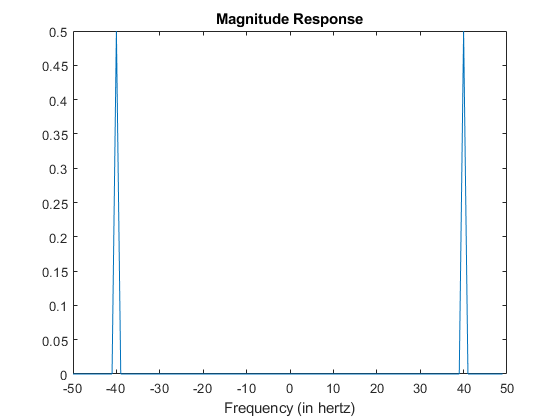

   %%Time specifications:
   Fs = 100;                      % samples per second
   dt = 1/Fs;                     % seconds per sample
   StopTime = 1;                  % seconds
   t = (0:dt:StopTime-dt)';
   N = size(t,1);

   %%Sine wave:
   Fc = 60;                       % hertz
   x = cos(2*pi*Fc*t);

   %%Fourier Transform:
   X = fftshift(fft(x));

   %%Frequency specifications:
   dF = Fs/N;                      % hertz
   f = -Fs/2:dF:Fs/2-dF;           % hertz

   %%Plot the spectrum:
   figure;
   poop = abs(X)/N;
   plot(f,poop);
   xlabel('Frequency (in hertz)');
   title('Magnitude Response');